# **EE6225 Assignment-3**

# Wu Tianwei

# Matriculation No. G2101446F

# e-mail: WU0008EI@e.ntu.edu.sg

## 1. Choose Sampling Time

First of all, the G(s) needs to be descretized with sampling time Ts. To determine Ts, I plot the open-loop unit step response of G(s).

clc;
clear;

% Define the transfer function matrix 
Gs = [tf(-0.98, [12.5, 1], 'inputDelay', 17), tf(-0.36, [15, 1], 'inputDelay', 27), ...
    tf(-0.14, [15.2, 1], 'inputDelay', 32);
    tf(-0.43, [14.7, 1], 'inputDelay', 25), tf(-0.92, [13, 1], 'inputDelay', 16), ...
    tf(-0.11, [15.6, 1], 'inputDelay', 33);
    tf(-0.12, [15, 1], 'inputDelay', 31), tf(-0.16, [15, 1], 'inputDelay', 34), ...
    tf(-1.02, [11.8, 1], 'inputDelay', 16)].';
Gs

Gs =
 
  From input 1 to output...
                      -0.98
   1:  exp(-17*s) * ----------
                    12.5 s + 1
 
                     -0.36
   2:  exp(-27*s) * --------
                    15 s + 1
 
                      -0.14
   3:  exp(-32*s) * ----------
                    15.2 s + 1
 
  From input 2 to output...
                      -0.43
   1:  exp(-25*s) * ----------
                    14.7 s + 1
 
                     -0.92
   2:  exp(-16*s) * --------
                    13 s + 1
 
                      -0.11
   3:  exp(-33*s) * ----------
                    15.6 s + 1
 
  From input 3 to output...
                     -0.12
   1:  exp(-31*s) * --------
                    15 s + 1
 
                     -0.16
   2:  exp(-34*s) * --------
                    15 s + 1
 
                      -1.02
   3:  exp(-16*s) * ----------
                    11.8 s + 1
 
Continuous-time transfer function.



Plot the unit step response of Gs.

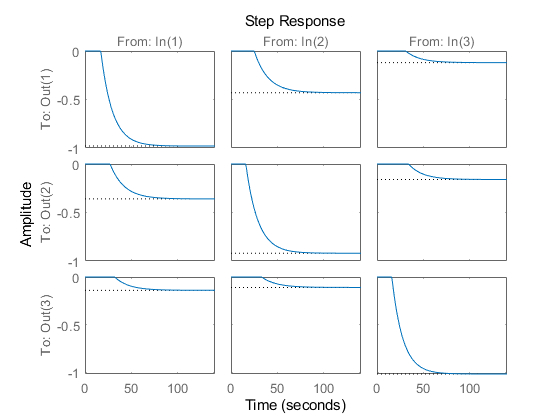

figure(1);
step(Gs);

According to the step responses, the shortest rise time is **25.9** seconds.

If the sampling time is too big, when a disturbance comes in, the controller won’t be able to react to the disturbance fast enough. On the contrary, if the sample time is too small, the controller can react much faster to disturbances and the changes of setpoint, but this leads to an excessive computational load. To find the right balance between performance and computational effort, I choose **2.5** seconds as sampling time Ts.

## 2. State space representation with u(k) as input

N_inputs = size(Gs, 1);

% Descretize Gs with sampling time ts
ts = 2.5;
Gz = c2d(Gs, ts);

% Get state space model for MPC design
Gz = absorbDelay(Gz);
Gz = ss(Gz);
Ap = Gz.A;
Bp = Gz.B;
Cp = Gz.C;
Dp = Gz.D;
n = size(Ap, 1);
m = size(Bp, 2);
p = size(Cp, 1);

% Design MPC
model = ss(Ap, Bp, Cp, Dp, ts);

size(Ap)

ans =    105   105


size(Bp)

ans =    105     3


size(Cp)

ans =      3   105


The dimensions of Ap, Bp, Cp will be different with regards to different sampling time.

## 3. State space representation with Δu(k) as input

% [Δx(k),y(k)]
A = [Ap, zeros(size(Ap, 1), size(Cp, 1)); Cp * Ap, eye(size(Cp, 1), size(Cp, 1))];
B = [Bp; Cp * Bp];
C = [zeros(size(Cp,1),size(Cp,2)), eye(size(Cp,1),size(Cp,1))];

size(A)

ans =    108   108


size(B)

ans =    108     3


size(C)

ans =      3   108


## 4. Effects of tuning knobs ---- N2, Nu, λ

### ① Effect of the output horizon, N2

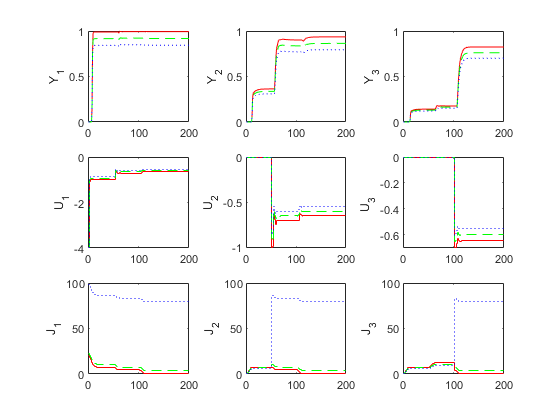

tsim = 200;
t = 1 : tsim;
figure(2);
% N1 = 1, N2 = 10, Nu = 5, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 10, 5, 0.01);

subplot(3, 3, 1);
plot(t, y1, '-r');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '-r');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '-r');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '-r');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '-r');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '-r');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '-r');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '-r');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '-r');
hold on;
ylabel('J_3');

% N1 = 1, N2 = 20, Nu = 5, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 20, 5, 0.01);

subplot(3, 3, 1);
plot(t, y1, '--g');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '--g');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '--g');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '--g');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '--g');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '--g');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '--g');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '--g');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '--g');
hold on;
ylabel('J_3');

% N1 = 1, N2 = 50, Nu = 5, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 5, 0.01);

subplot(3, 3, 1);
plot(t, y1, ':b');
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, ':b');
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, ':b');
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, ':b');
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, ':b');
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, ':b');
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, ':b');
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, ':b');
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, ':b');
ylabel('J_3');

Nu = 5, Lambda = 0.01

N2 = 10 ---- Solid, N2 = 20 ---- Dashed, N2 = 50 ---- Dotted

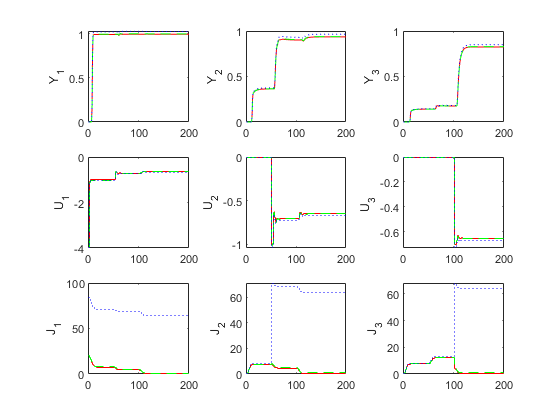

tsim = 200;
t = 1 : tsim;
figure(3);
% N1 = 1, N2 = 10, Nu = 10, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 10, 10, 0.01);

subplot(3, 3, 1);
plot(t, y1, '-r');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '-r');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '-r');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '-r');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '-r');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '-r');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '-r');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '-r');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '-r');
hold on;
ylabel('J_3');

% N1 = 1, N2 = 20, Nu = 10, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 20, 10, 0.01);

subplot(3, 3, 1);
plot(t, y1, '--g');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '--g');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '--g');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '--g');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '--g');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '--g');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '--g');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '--g');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '--g');
hold on;
ylabel('J_3');

% N1 = 1, N2 = 50, Nu = 10, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 10, 0.01);

subplot(3, 3, 1);
plot(t, y1, ':b');
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, ':b');
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, ':b');
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, ':b');
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, ':b');
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, ':b');
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, ':b');
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, ':b');
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, ':b');
ylabel('J_3');

Nu = 10, Lambda = 0.01

N2 = 10 ---- Solid, N2 = 20 ---- Dashed, N2 = 50 ---- Dotted

As we can see from the plots, when Nu is small, increasing N2 causes the loop dynamics to slow down. When Nu is large, increasing N2 won't improve performance.

### ② Effect of the control horizon, Nu

N2 = 50 for different Nu

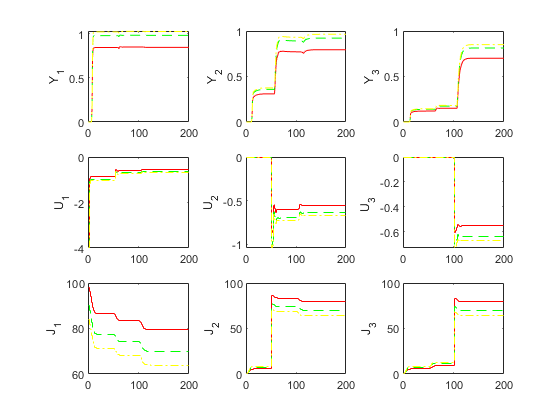

tsim = 200;
t = 1 : tsim;
figure(4);
% N1 = 1, N2 = 50, Nu = 5, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 5, 0.01);

subplot(3, 3, 1);
plot(t, y1, '-r');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '-r');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '-r');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '-r');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '-r');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '-r');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '-r');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '-r');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '-r');
hold on;
ylabel('J_3');

% N1 = 1, N2 = 50, Nu = 8, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 8, 0.01);

subplot(3, 3, 1);
plot(t, y1, '--g');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '--g');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '--g');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '--g');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '--g');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '--g');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '--g');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '--g');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '--g');
hold on;
ylabel('J_3');

% N1 = 1, N2 = 50, Nu = 10, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 10, 0.01);

subplot(3, 3, 1);
plot(t, y1, '-.y');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '-.y');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '-.y');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '-.y');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '-.y');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '-.y');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '-.y');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '-.y');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '-.y');
hold on;
ylabel('J_3');

Nu = 5 ---- Solid, Nu = 8 ---- Dashed, Nu = 10 ---- Dash-Dot

As we can see from the plots, when N2 is large, increasing Nu will improve performance.

### ③ Effect of the control weighting, λ

N2 = 50, Nu = 10 for different λ

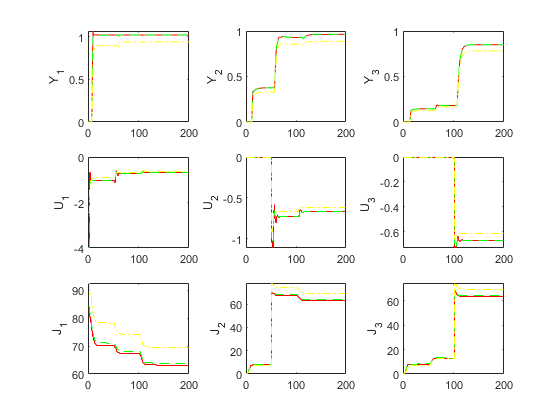

tsim = 200;
t = 1 : tsim;
figure(5);
% N1 = 1, N2 = 50, Nu = 10, Lambda = 0.001
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 10, 0.001);

subplot(3, 3, 1);
plot(t, y1, '-r');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '-r');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '-r');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '-r');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '-r');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '-r');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '-r');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '-r');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '-r');
hold on;
ylabel('J_3');

% N1 = 1, N2 = 50, Nu = 10, Lambda = 0.01
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 10, 0.01);

subplot(3, 3, 1);
plot(t, y1, '--g');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '--g');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '--g');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '--g');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '--g');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '--g');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '--g');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '--g');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '--g');
hold on;
ylabel('J_3');

% N1 = 1, N2 = 50, Nu = 10, Lambda = 0.1
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 10, 0.1);

subplot(3, 3, 1);
plot(t, y1, '-.y');
hold on;
ylabel('Y_1');
subplot(3, 3, 4);
stairs(t, u1, '-.y');
hold on;
ylabel('U_1');
subplot(3, 3, 7);
stairs(t, j1, '-.y');
hold on;
ylabel('J_1');

subplot(3, 3, 2);
plot(t, y2, '-.y');
hold on;
ylabel('Y_2');
subplot(3, 3, 5);
stairs(t, u2, '-.y');
hold on;
ylabel('U_2');
subplot(3, 3, 8);
stairs(t, j2, '-.y');
hold on;
ylabel('J_2');

subplot(3, 3, 3);
plot(t, y3, '-.y');
hold on;
ylabel('Y_3');
subplot(3, 3, 6);
stairs(t, u3, '-.y');
hold on;
ylabel('U_3 ');
subplot(3, 3, 9);
stairs(t, j3, '-.y');
hold on;
ylabel('J_3');

λ = 0.001 ---- Solid, λ = 0.01 ---- Dashed, λ = 0.1 ---- Dash-Dot

As we can see from the plots, when λ increases, the response will slow down.

## 5. MPC Design and comparison with PID controllers

### ① Decentralized control

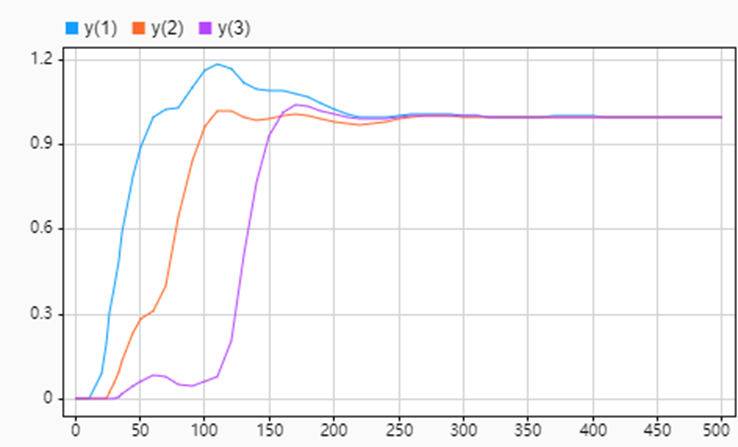

### ② Sparse control

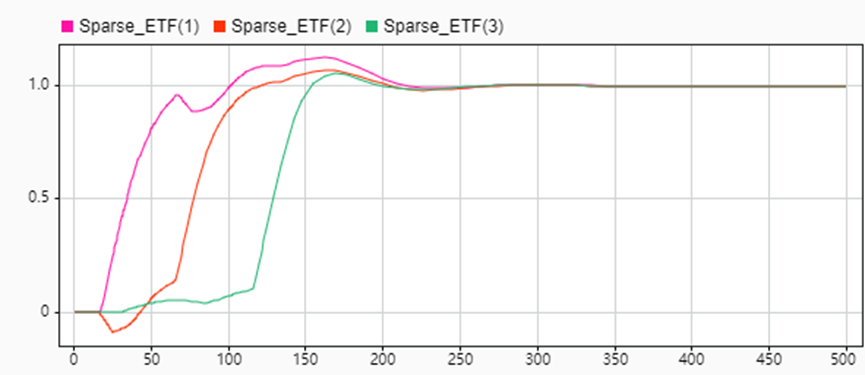

### ③ Decoupling control

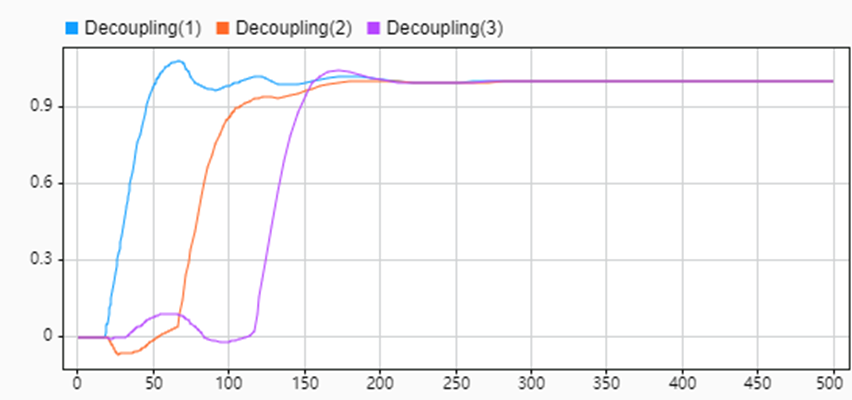

### ④ MPC

N1 = 1, N2 = 50, Nu = 10, λ = 0.01, Umin = -4, Umax = 4

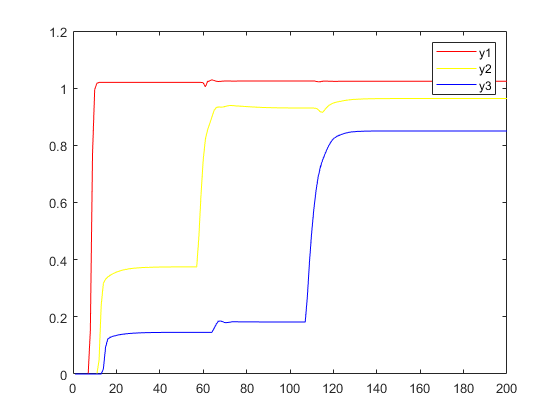

tsim = 200;
t = 1 : tsim;
[y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(1, 50, 10, 0.01);
figure(6);
plot(t, y1, 'r', t, y2, 'y', t, y3, 'b');
legend('y1', 'y2', 'y3');

Compared with PID controllers, my MPC design doesn't perform as well as Decentralized control, Sparse control and Decoupling control. My MPC design can't have zero steady error, but it converges more quickly than those PID controllers. And when I'm designing my MPC model, I just need to care about the A, B, C in the state space representation of the plant model. Obviously, it's more easier to implement MPC method than classical PID controllers. I also tried MPC Toolbox in Matlab to design the controller. It performs quite well. (Codes are in the mpcToolBox.m)

## 6. Pros and cons of the MPC method

### Pros:

1) Unlike PID controller, MPC method can handle multivariable control problem more easily.

2) MPC method is easy to tune.

3) MPC method can deal with constrains more easily and the concept is simple.

4) MPC method is very useful when future references are known.

### Cons:

1) The derivation of the control law is more complex than that of classical PID controllers.

2) When constraints are taken into consideration, the amount of computation is quite high.

### 7. Functions used in the Matlab Program

function [y1, y2, y3, u1, u2, u3, j1, j2, j3] = MPC(N1, N2, Nu, Lambda)
    % Define the transfer function matrix 
    Gs = [tf(-0.98, [12.5, 1], 'inputDelay', 17), tf(-0.36, [15, 1], 'inputDelay', 27), ...
        tf(-0.14, [15.2, 1], 'inputDelay', 32);
        tf(-0.43, [14.7, 1], 'inputDelay', 25), tf(-0.92, [13, 1], 'inputDelay', 16), ...
        tf(-0.11, [15.6, 1], 'inputDelay', 33);
        tf(-0.12, [15, 1], 'inputDelay', 31), tf(-0.16, [15, 1], 'inputDelay', 34), ...
        tf(-1.02, [11.8, 1], 'inputDelay', 16)].';

    % Descretize Gs with sampling time ts
    ts = 2.5;
    Gz = c2d(Gs, ts);

    % Get state space model for MPC design
    Gz = absorbDelay(Gz);
    Gz = ss(Gz);
    Ap = Gz.A;
    Bp = Gz.B;
    Cp = Gz.C;
    Dp = Gz.D;
    n = size(Ap, 1);
    m = size(Bp, 2);
    p = size(Cp, 1);

    % Design MPC
    model = ss(Ap, Bp, Cp, Dp, ts);

    Phi = zeros((N2 - N1 + 1) * p, n);
    G = zeros((N2 - N1 + 1) * p, m * Nu);

    for i = N1 : N2
        Phi((i - 1) * p + 1 : i * p, :) = Cp * Ap^i;
        for k = 1 : Nu
            if i - k >= 0
                G((i - 1) * p + 1 : i * p, m * (k - 1) + 1 : m * k) = ...
                Cp * Ap^(i - k) * Bp;
            else
                break;
            end
        end
    end
    
    % Prediction horizon
    tsim = 200;
    
    SetPt = ones(tsim, 3);
    SetPt(1 : 50, 2) = 0;
    SetPt(1 : 100, 3) = 0;

    x = zeros(n, 1);

    y1 = zeros(tsim, 1);
    y2 = zeros(tsim, 1);
    y3 = zeros(tsim, 1);
    u1 = zeros(tsim, 1);
    u2 = zeros(tsim, 1);
    u3 = zeros(tsim, 1);
    j1 = zeros(tsim, 1);
    j2 = zeros(tsim, 1);
    j3 = zeros(tsim, 1);

    for k = 1 : tsim
        wk = SetPt(k, :);
        xk = x;
        yk = Cp * xk;

        % Compute the MPC control signal
        % Constrained
        [U1, J1] = MPC_MIMO(wk, xk, Phi, G, m, N1, N2, Nu, Lambda, 1, -4, 4);
        [U2, J2] = MPC_MIMO(wk, xk, Phi, G, m, N1, N2, Nu, Lambda, 2, -4, 4);
        [U3, J3] = MPC_MIMO(wk, xk, Phi, G, m, N1, N2, Nu, Lambda, 3, -4, 4);
        if k <= 50
            uk = [U1(1, 1), 0, 0];
        elseif k <= 100
            uk = [U1(1, 1), U2(1, 1), 0];
        else
            uk = [U1(1, 1), U2(1, 1), U3(1, 1)];
        end

        x = Ap * xk + Bp * uk';

        y1(k) = yk(1, 1);
        y2(k) = yk(2, 1);
        y3(k) = yk(3, 1);
        u1(k) = uk(1);
        u2(k) = uk(2);
        u3(k) = uk(3);
        j1(k) = J1;
        j2(k) = J2;
        j3(k) = J3;
    end
end

function [U, J] = MPC_MIMO(wk, xk, Phi, G, m, N1, N2, Nu, Lambda, ...
    N_input, MIN, MAX)
    cvx_begin quiet
        variable U(m * Nu, 1)
        Y = Phi * xk + G * U;
        W = ones(size(Y, 1), 1) * wk(N_input);
        OBJ = (W - Y)' * (W - Y) + Lambda * (U' * U);
        minimize(OBJ);
        
        % Add constrains on U
        UMIN = MIN * ones(size(U, 1), 1);
        UMAX = MAX * ones(size(U, 1), 1);
        subject to
            UMIN <= U <= UMAX;
    cvx_end
    J = cvx_optval;
end